**3.**

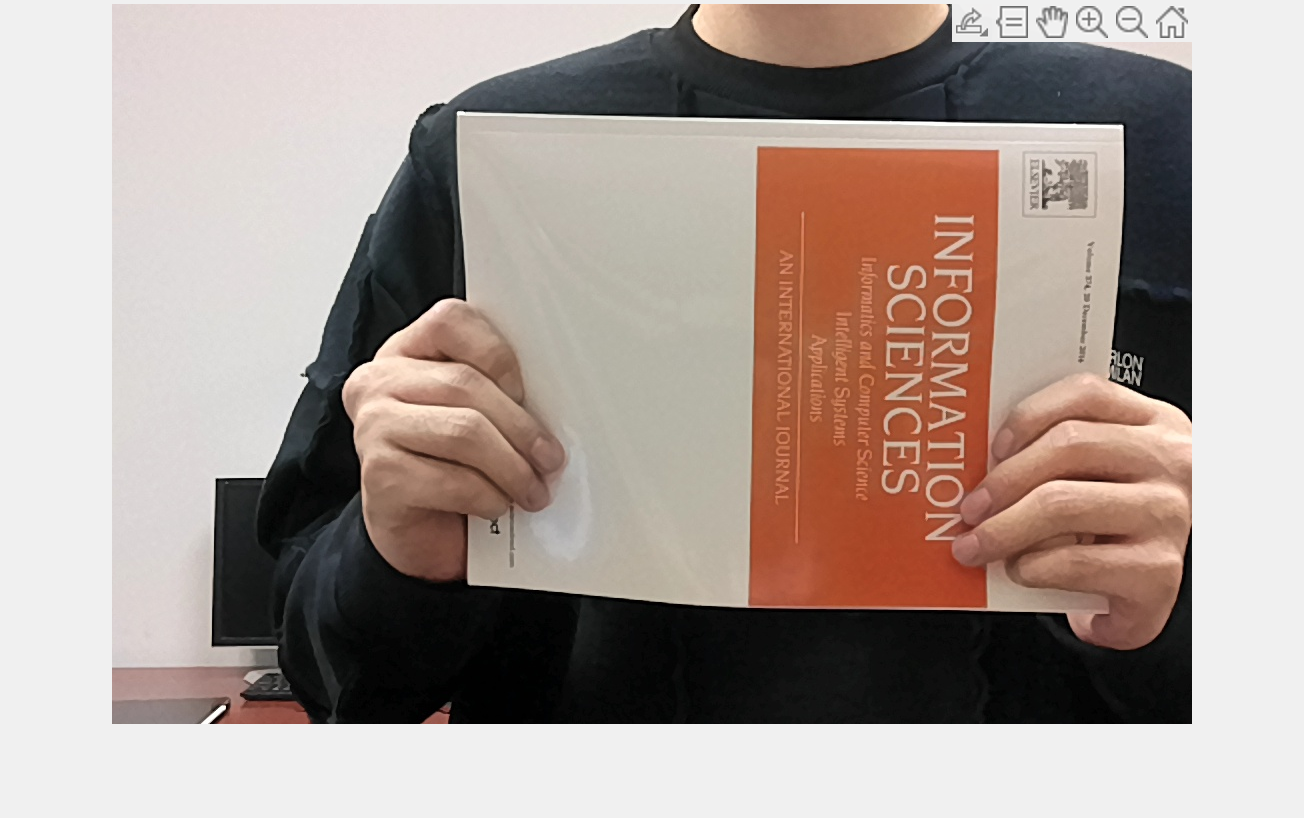

x =          350
        1012


y =    102
   118


I = imread("./images/book.jpg");
imshow(I);

% let the user choose 2 points on the image
[x y] = ginput(2)


% focal length of camera calibration
f = 1.836303860760159e+03;

% distance between camera and chessboard
z0 = 644;

% Calculate real world coordinates from image coordinates
x0 = z0 * (x(1) / f);
x1 = z0 * (x(2)/ f);

y0 = z0 * (y(1) / f);
y1 = z0 * (y(2) / f);

distance = sqrt((x1-x0)^2 + (y1 - y0)^2)

distance = 232.2342

The 2 points chosen are the ending point of the edge of the book in the image. The actual length of the edge of book shown above is 26cm, and the estimated length is about 23.2cm, which is close to the actual value.